clc
clear
close all

Gqn0=[16,64,256,1024,4096,16384,65536,262144]*1e-6;
vv=[10,20,40,60];

b = 1.5;        % 轮距（m）
L = 4.0;        % 轴距（m）
v = vv(3);      % 车速（m/s）
n0  = 0.1;      % 参考空间频率     （m-1）
n00 = 0.01;     % 路面空间截止频率 （m-1）
Gqn0 = Gqn0(2); % 选择路面等级

## 矩阵参数输入

% syms n00 v b L n0 Gqn0 
% 获得LaTeX公式、图片、MathML
%   1.取消注释上一行（syms）和此节最后两行（disp(A)）
%   2.注意需单独运行此节
a1 = -2*pi*n00*v;
a2 = v/b*exp(-2*pi*n00*b);
a3 = -12*v/L;
a4 = -v/b;
a5 = 72*v^2/L^2;
a6 = -12*v^2/L^2;
a7 = a3/2;

b1 = 2*pi*n0*sqrt(Gqn0*v);

A = [a1 0 0 0 0 0;a2 a4 0 0 0 0;a3+a1 0 0 0 0 1;a2 a3+a4 0 0 0 1;a3 0 0 0 0 1;a5 0 0 0 a6 a7];
B = [b1 0 b1 0 0 0]';
disp(A);

   1.0e+03 *

  列 1 至 5

   -0.0025         0         0         0         0
    0.0243   -0.0267         0         0         0
   -0.1225         0         0         0         0
    0.0243   -0.1467         0         0         0
   -0.1200         0         0         0         0
    7.2000         0         0         0   -1.2000

  列 6

         0
         0
    0.0010
    0.0010
    0.0010
   -0.0600



disp(B);

    0.0318
         0
    0.0318
         0
         0
         0



% white noise参数设置
noise_power = 0.1;       % 噪声功率
sample_time = 0.001;     % 采样时间
seed = 23341;            % 随机种子

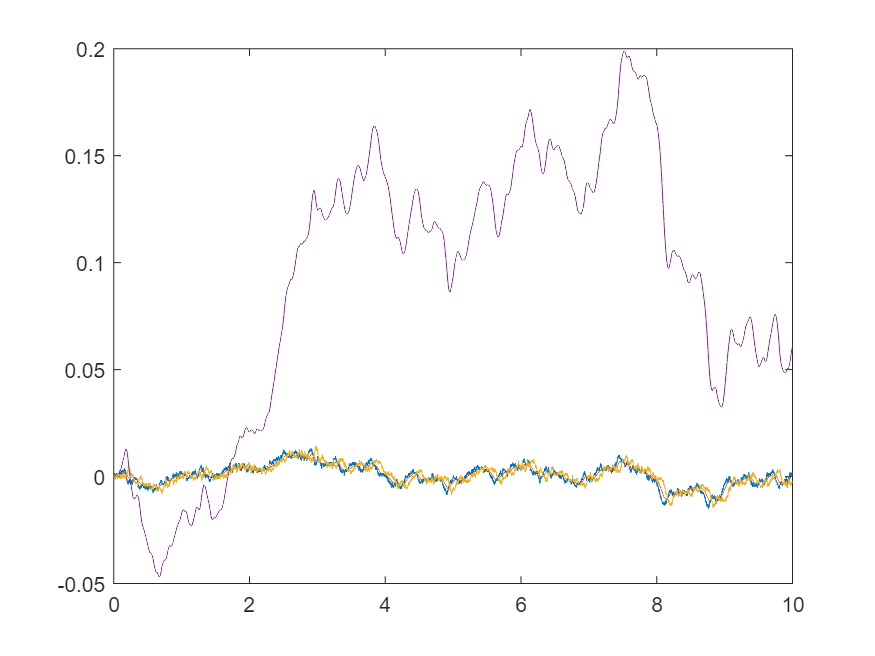

% simulink 求解
options=simset('Srcworkspace','current');
out=sim('P5_son.slx',[0,10]);
% noise_x = out.noise.Time;
% noise_y = out.noise.Data;
% 
t = out.simout.Time;
y = out.simout.Data;

plot(t,y(:,1:4));